Ejemplo de estimador de media muestral

Inicia con la generación de datos de la señal observada. Al nivel DC se le suma una señal de ruido que se obtiene a partir de una distribución de probabilidad

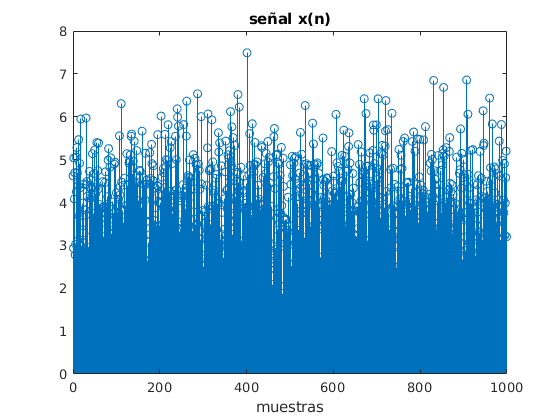

%Ejemplo Estimador de media muestral con mínimos cuadrados
A=4; % valor DC de la señal x(n) "desconocido"
N=1000; % número de muestras de x(n)
xn=A+normrnd(0,1,N,1); % señal con ruido Gaussiano (media=0, sigma=1)
stem([0:N-1],xn)
xlabel('muestras')
title('señal x(n)')

Se aplicará el estimador de media muestral 

% punto de partida o estimación inicial
A_h=mean(xn);
%A_h=xn(1); %estimador de muestra inicial

Hasta acá se tendría la estimación (A_h) del parámetro desconocido

cd=sprintf('Valor estimado: %8.6f',A_h);
disp(cd)

Valor estimado: 3.922166


error = abs(A-A_h)

error = 0.0778

Ahora, mediante la aplicación del algoritmo de gradiente descendente se hará una optimización del estimador.

%parametros del algoritmo de optimizacion
stop = 1;
step=0.1;
max_iter=500;
iter=0;
% loop de optimización
while stop > 0.0000000001 & iter<max_iter
    A_hp=A_h;
    err=sum((xn-A_h))/N;
    A_h=A_h+step*err;
    stop = abs(A_h-A_hp);
    iter = iter+1;
end
cd=sprintf('Valor optimizado: %8.6f',A_h);
disp(cd)

Valor optimizado: 3.922166


error = abs(A-A_h)

error = 0.0778